# Import/Export Data

## **NOTE:** You must have the Grades.xlsx file downloaded to the same folder as this live script for the import functions to work properly.

Often, we want to use MATLAB to manipulate data generated with other software. Similarly, we might want to create data in MATLAB that can be used in other programs. This requires us to understand importing and exporting data with MATLAB.

## A Typical Example – Manipulating Grades

Manipulating grades is a classic example used to discuss importing/exporting data. It is convenient to create gradebooks using electronic spreadsheet software (e.g., Excel), but the data manipulation is often cleaner using a scientific programming language (e.g., MATLAB). Consider the Excel data shown in the screenshot below. We want to import this data to MATLAB and manipulate it accordingly.

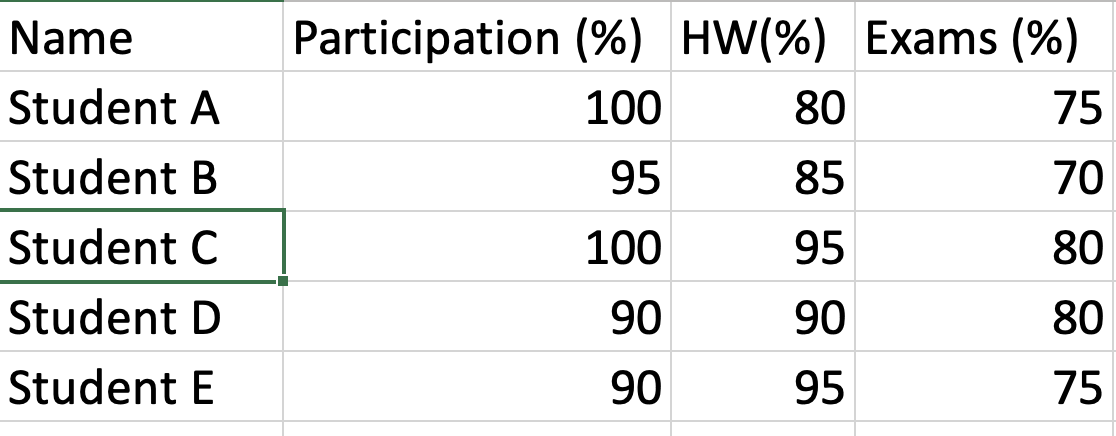

There are a few ways we can import this data. Let's first focus on just the numerical values, which is the most important stuff, anyway. When all the data we want to import is numerical, we can directly import it to a matrix. We do this using the [`readmatrix`](https://www.mathworks.com/help/matlab/ref/readmatrix.html) command in MATLAB. The simplest way to use this command is

This stores the data from the desired file to a matrix `A`. 

 % store the data in Grades.xlsx to the variable A

Notice that the first row of the data (the column headers) was not imported and that the first column was imported but stored as 'NaN' (not a number). This is a consequence of some default settings of the `readmatrix` command:

- The first row is ignored if all the entries are `NaN`

- All other entries are imported as their numerical values or `NaN`

We don't want the `NaN` column, since that is just a placeholder for the students' names. There are many ways we can remove this column. One way is using the [`rmmissing`](https://www.mathworks.com/help/matlab/ref/rmmissing.html?s_tid=doc_ta) command, which can remove rows or columns of matrices that have missing data.

% remove columns of A that have missing data (e.g., NaN)

Now that the grade data is stored to a matrix, we can manipulate it just like any other matrix.

Create a new column in matrix `A` that represents the overall grade for each student. Use the bin weight represented by the vector `w`, defined below.

w = [10 30 60]; % overall grade bin weight, in %
% create 4th column of A

Now that we have calculated each student's overall course grade, we would like to export the grades back to Excel. We can do this using [`writematrix`](https://www.mathworks.com/help/matlab/ref/writematrix.html?s_tid=doc_ta). The general syntax is

% write matrix A to a file called Grades_Final.xlsx

Note that `A` does not have the first row (the column headers) or the first column (the student names) contained in the original Grades file. There are a few ways we could fix this. The most straightforward way is to probably have imported the original Grades data as a table instead of a matrix.

## MATLAB Table Arrays

[Table arrays](https://www.mathworks.com/help/matlab/ref/table.html?searchHighlight=table&s_tid=srchtitle_table_1) allow us to store strings (i.e., words) and doubles (i.e., numbers) to the same variable. We can read in data to a table using [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html).

 % create table T from Grades.xlsx

The `readtable` function reads in the table headers as variable names. The warning is due to the fact that variable names in MATLAB can't have spaces or special characters (e.g., % and parentheses), so these characters are converted to underscores in the table header row. There are many ways to access data in a table.

Access the values in a column using the syntax

Create smaller tables by calling select elements using the syntax

Note that the first row of the table is the row below the table headers. For example, to create a new table excluding student A, we write

 % 

Create a matrix of select entries using the syntax

For this to work, all the entries must be of the same data type (e.g., double or string). To create a matrix of just the numerical percentages of the grades for each student, we write

To append a column to a table, we use the syntax

Create new column of T with the variable name `Final_Grade` that represents each student's final grade. The bin weights are copied again below for convenience.

w = [10 30 60]; % overall grade bin weight, in %


Now we can write this table to a file using `writetable`. Let's write the table to a text file.

writetable(T,'Final_Grades.xlsx')

### You Try It

Note: This is HW05 P01. It is probably best for you to open a new script file and complete these tasks there so that you can easily translate your work to MATLAB Grader at a later date.

Domantas Sabonis plays Center for the Sacramento Kings (Professor Wilbur's favorite NBA team). One way coaches, fans, and analysts assess a player's performance is via their per-game stats. Based on these per-game stats, Sabonis is arguably having the best year of his career during this current 2023-2024 season. A great, free reference for finding these basketball stats is [Basketball Reference](https://www.basketball-reference.com/). Anybody can access this website and find statistics for pretty much any current and former professional basketball player.

Professor Wilbur downloaded Sabonis's **total stats **for his career and saved them to the text file 'Sabonis_Totals_BBallRef.txt'. Your task is to import this data (probably best as a table so that non-number information is maintained) and use it to calculate Sabonis's per-game (G) totals in points (PTS), rebounds (TRB), assists (AST), steals (STL), and blocks (BLK) for each year of his career. Note that during the 2021-2022 season Sabonis played for 2 different teams and his statistics for that season are separated in this data. The row labeled 'TOT' includes all of his stats from the 2021-2022 NBA season.

Based solely on this per-game data, can you make an argument that Sabonis is having the best year of his career?

#### Deliverables (for HW05 P01)

You should save each of these per-game totals as a column vector where the first element represents Sabonis's per-game stats for his first season in the league (2016-2017) and the last element represents his per-game totals for the current season (2023-2024). Your column vectors should just include numerical values; that is, you are not making a table out of this data but instead are just creating these column vectors. Your script should calculate 5 vectors:

- A vector called **PTS** that stores Sabonis's points per game for each of his seasons.

- A vector called **TRB** that stores Sabonis's rebounds per game for each of his seasons.

- A vector called **AST** that stores Sabonis's assists per game for each of his seasons.

- A vector called **STL** that stores Sabonis's steals per game for each of his seasons.

- A vector called **BLK** that stores Sabonis's blocks per game for each of his seasons.